% generate_rednoise.m
% This is program generate red noise from the sequence of white noise
% Priya 26/12/22
% reference: https://atmos.washington.edu/~breth/classes/AM582/lect/lect8-notes.pdf

lseq = 10000;
wn2 = randn(1,lseq);
rn = zeros(1,lseq);
rn(1)=wn2(1);
rcc = 0.5

rcc = 0.5000

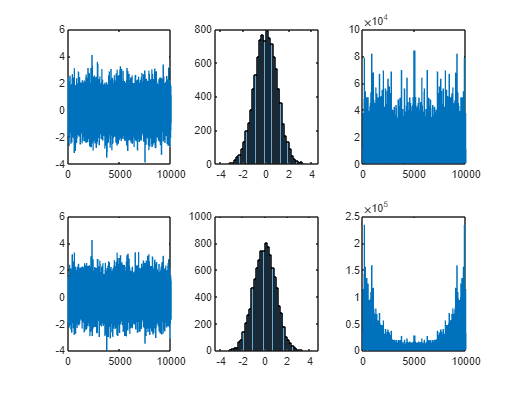


% generate red noise from the above white noise

for idx = 2:lseq
     rn(1,idx)=rcc*rn(1,idx-1)+(1-rcc^2)^(0.5)*wn2(1,idx); 
end

% plotting the white and red noises

subplot(2,3,1);
plot(wn2);
subplot(2,3,2)
histogram(wn2);
subplot(2,3,3)
swn = abs(fft(wn2));
pwn = swn.^2;
plot(pwn);
subplot(2,3,4);
plot(rn);
subplot(2,3,5);
histogram(rn);
subplot(2,3,6);
srn = abs(fft(rn));
prn = srn.^2;
plot(prn);